# Laboratorium 9

### Parametry sygnałów cyfrowych

Janusz Pawlicki

## 1. Wstęp

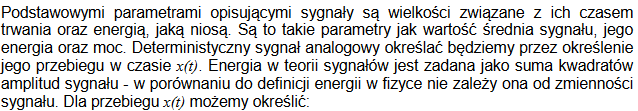

                                                                               (1)

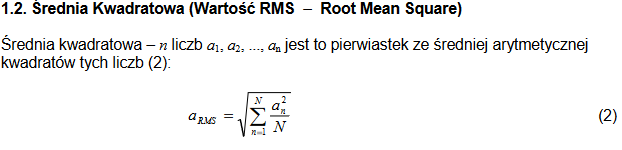

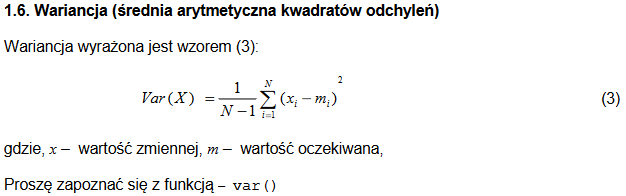

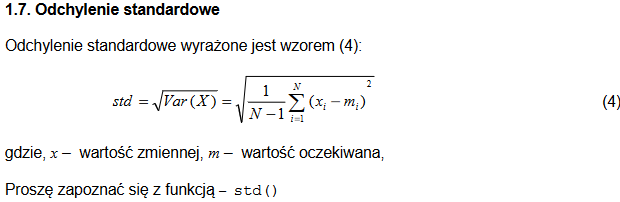

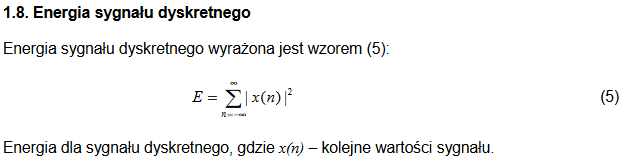

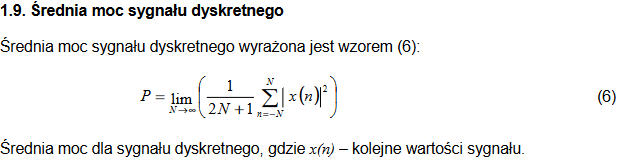

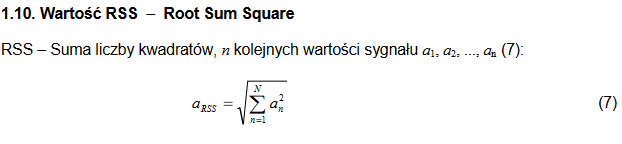

## 2. Przebieg laboratorium

load dane.mat

### Zadanie 1

Obliczyć wartość średnią z sygnałów `X=[0, 1, 3]`, `wiatrak20.wav, przekladnia20.wav`

X_sr = mean(X)

X_sr = 1.3333

wiatrak_sr = mean(wiatrak_data)

wiatrak_sr = -2.4346e-05

przek_sr = mean(przekladnia_data)

przek_sr = -4.2175e-04

### Zadanie 2

Obliczyć RMS z sygnałów `X=[0, 1, 3], wiatrak20.wav, przekladnia20.wav`

X_rms = rms(X)

X_rms = 1.8257

wiatrak_rms = rms(wiatrak_data)

wiatrak_rms = 0.1855

przek_rms = rms(przekladnia_data)

przek_rms = 0.1415

### Zadanie 3

Obliczyć współczynnik szczytu z sygnałów `X=[0, 1,` `3], wiatrak20.wav, przekladnia20.wav`

X_peak = peak2rms(X)

X_peak = 1.6432

wiatrak_peak = peak2rms(wiatrak_data)

wiatrak_peak = 4.2778

przek_peak = peak2rms(przekladnia_data)

przek_peak = 4.7018

### Zadanie 4

Obliczyć współczynnik peak-to-peak z sygnałów `X=[0, 1, 3], wiatrak20.wav, przekladnia20.wav`

X_p2p = peak2peak(X)

X_p2p = 3

wiatrak_p2p = peak2peak(wiatrak_data)

wiatrak_p2p = 1.5757

przek_p2p = peak2peak(przekladnia_data)

przek_p2p = 1.2662

### Zadanie 5

Obliczyć wartość maksymalną i minimalną z sygnałów `X=[0, 1, 3],` `wiatrak20.wav, przekladnia20.wav`

X_min = min(X)

X_min = 0

X_max = max(X)

X_max = 3

wiatrak_min = min(wiatrak_data)

wiatrak_min = -0.7821

wiatrak_max = max(wiatrak_data)

wiatrak_max = 0.7936

przek_min = min(przekladnia_data)

przek_min = -0.6008

przek_max = max(przekladnia_data)

przek_max = 0.6654

### Zadanie 6

Obliczyć wariancję z sygnałów `X=[0, 1, 3], wiatrak20.wav, przekladnia20.wav`

X_var = var(X)

X_var = 2.3333

wiatrak_var = var(wiatrak_data)

wiatrak_var = 0.0344

przek_var = var(przekladnia_data)

przek_var = 0.0200

### Zadanie 7

Obliczyć odchylenie standardowe z sygnałów `X=[0, 1, 3], wiatrak20.wav, przekladnia20.wav`

X_std = std(X)

X_std = 1.5275

wiatrak_std = std(wiatrak_data)

wiatrak_std = 0.1855

przek_std = std(przekladnia_data)

przek_std = 0.1415

### Zadanie 8

Obliczyć energię z sygnałów `X=[0, 1, 3], wiatrak20.wav, przekladnia20.wav`

X_energy = sum(abs(X).^2)

X_energy = 10

wiatrak_energy = sum(abs(wiatrak_data).^2)

wiatrak_energy = 1.5179e+03

przek_energy = sum(abs(przekladnia_data).^2)

przek_energy = 883.1704

### Zadanie 9

Obliczyć średnią moc z sygnałów: `X=[0, 1,` `3], wiatrak20.wav, przekladnia20.wav`, funkcji kosinus:

`t` `=` `0:0.001:1-0.001;`

`X` `=` `cos(2*pi*100*t);`

t = 0 : 0.001 : 1-0.001;
x = cos(2*pi*100*t);
X_bandp = bandpower(X)

X_bandp = 3.3333

wiatrak_bandp = bandpower(wiatrak_data)

wiatrak_bandp = 0.0344

przek_bandp = bandpower(przekladnia_data)

przek_bandp = 0.0200

x_bandp = bandpower(x)

x_bandp = 0.5000

### Zadanie 10

Obliczyć RSS z sygnałów: `X=[0, 1, 3], wiatrak20.wav, przekladnia20.wav`

X_rss = rssq(X)

X_rss = 3.1623

wiatrak_rss = rssq(wiatrak_data)

wiatrak_rss = 38.9602

przek_rss = rssq(przekladnia_data)

przek_rss = 29.7182

### Zadanie 11

Zapoznać się z funkcją do obliczania okresu sekwencji – `seqperiod()`

Obliczyć funkcję `seqperiod()` dla:

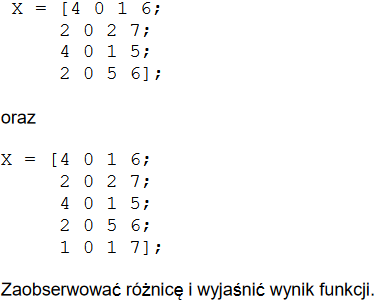

X1 = [4 0 1 6; 2 0 2 7; 4 0 1 5; 2 0 5 6];
X2 = [4 0 1 6; 2 0 2 7; 4 0 1 5; 2 0 5 6; 1 0 1 7];
X1_seq = seqperiod(X1)

X1_seq =      2     1     4     3


X2_seq = seqperiod(X2)

X2_seq =      5     1     4     3


### Zadanie 12

Zapoznać się z funkcją – `findpeaks()`

Znaleźć wartości szczytów (maksimów lokalnych) w sygnale:

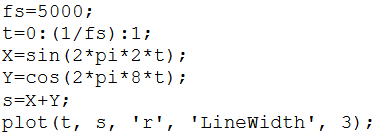

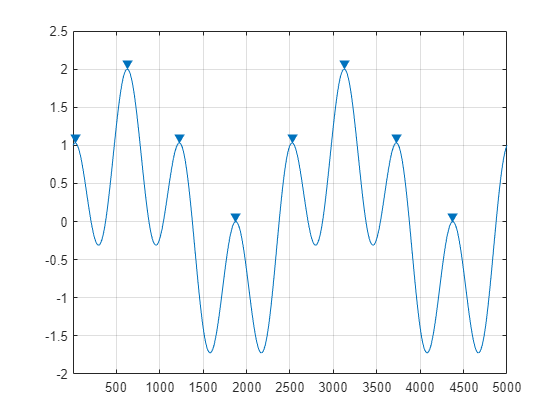

fs = 5000;
t = 0:(1/fs):1;
X = sin(2*pi*2*t);
Y = cos(2*pi*8*t);
s = X + Y;
findpeaks(s)

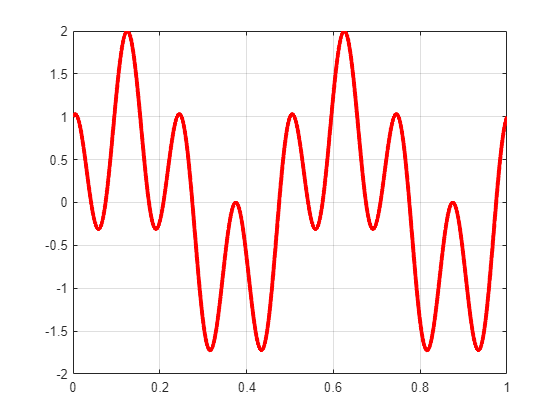

figure
plot(t, s, 'r', 'LineWidth',3);
grid on;

### Zadanie 13

Zapoznać się z funkcją – `findpeaks()`

Znaleźć lokalizację i wartości szczytów (maksimów lokalnych) w sygnale:

### 

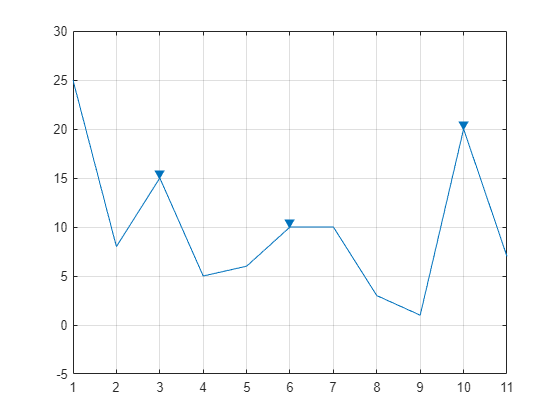

s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s)

### Zadanie 14

Zapoznać się z funkcją – `findpeaks(). `Znaleźć lokalizację i wartości szczytów (maksimów lokalnych) oraz posortować od

największego maksimum w sygnale:

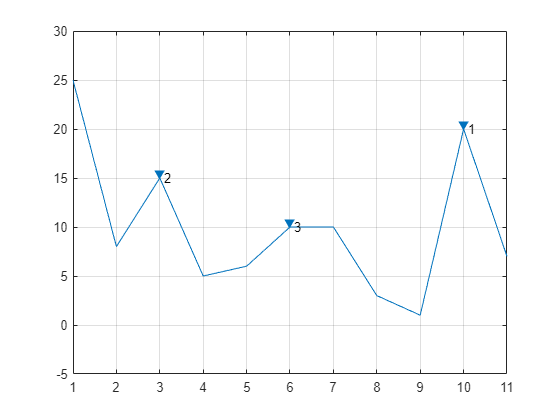

s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s)
[PEAKS_s, lokalizacja] = findpeaks(s,'SortStr','descend');
text(lokalizacja +0.1, PEAKS_s,num2str((1:numel(PEAKS_s))'))

### Zadanie 15

Zapoznać się z funkcją – `findpeaks(). `Znaleźć lokalizację i wartości szczytów (maksimów lokalnych). dla sygnału:

Zastosować parametr `'Threshold'`. Zaobserwować co się stanie dla wartości parametru `'Threshold'` równego 10, 5 i 0

x = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11];
s = [25 8 15 5 6 10 10 3 1 20 7];
th0 = 0;
th5 = 5;
th10 = 10;
findpeaks(s, 'Threshold', th0)

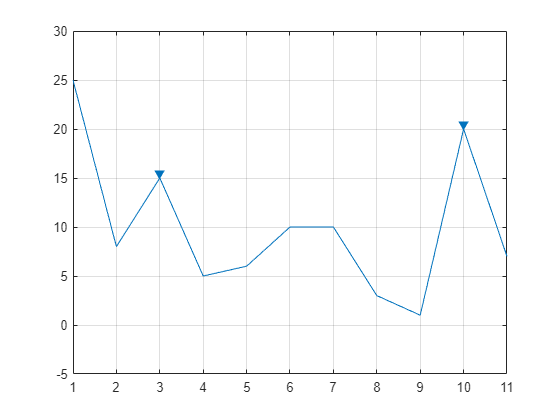

findpeaks(s, 'Threshold', th5)

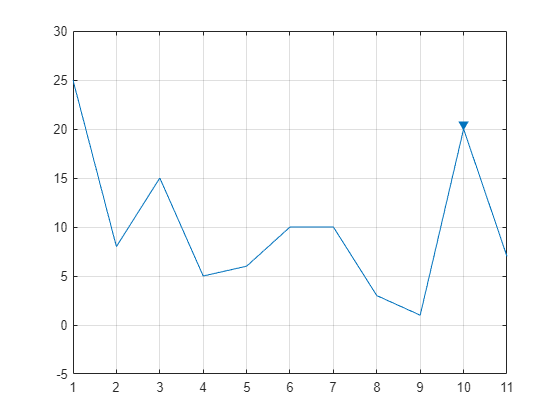

findpeaks(s, 'Threshold', th10)

### Zadanie 16

Zapoznać się z funkcją – `findpeaks()`

Znaleźć lokalizację i wartości szczytów (maksimów lokalnych) dla sygnału:

Zastosować parametr `'MinPeakHeight'`. Zaobserwować co się stanie dla wartości parametru `'MinPeakHeight'` równego 12, 8 i 3

x = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11];
s = [25 8 15 5 6 10 10 3 1 20 7];
mph3 = 3;
mph8 = 8;
mph12 = 12;

mph12 = 12

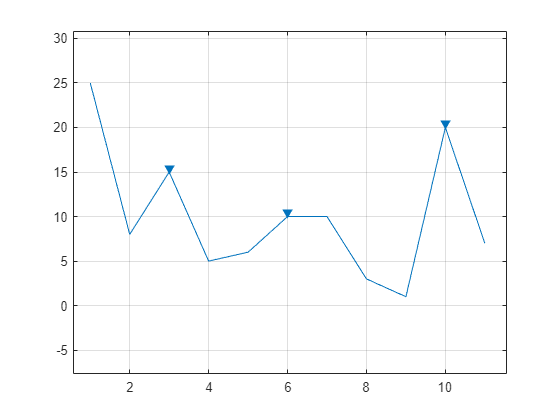

findpeaks(s, 'MinPeakHeight', mph3);

findpeaks(s, 'MinPeakHeight', mph8);

findpeaks(s, 'MinPeakHeight', mph12);

### Zadanie 17

Zapoznać się z funkcją – `findpeaks(). `Znaleźć lokalizację i wartości szczytów (maksimów lokalnych). dla sygnału:

Zastosować parametr `'NPeaks'`. Zaobserwować co się stanie dla wartości parametru `'NPeaks'` równego 1 i 2.

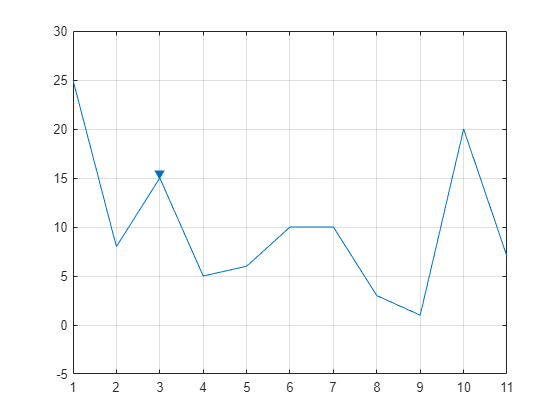

x = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11];
s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s, 'NPeaks', 1)

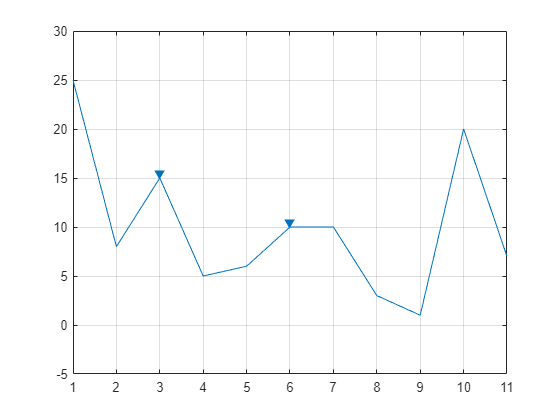

findpeaks(s, 'NPeaks', 2)

### Zadanie 18

Zapoznać się z funkcją – `findpeaks(). `Znaleźć lokalizację i wartości szczytów (maksimów lokalnych). dla sygnału:

Zastosować parametr `'MinPeakWidth'`. Zaobserwować co się stanie dla wartości parametru `'MinPeakWidth'` równego 1.

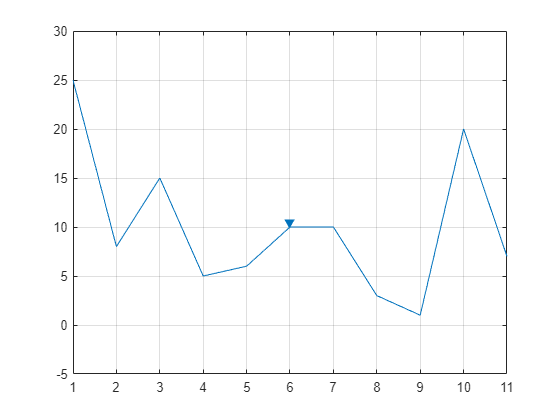

x = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11];
s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s, 'MinPeakWidth', 1)

### Zadanie 19

Korzystając z funkcji `rms()`, przeprowadzić rozpoznawanie na próbkach WAV (`wiatrak20.wav, wiatrak21.wav, wiatrak23.wav, wiatrak24.wav, przekladnia20.wav,` `przekladnia21.wav, przekladnia23.wav, przekladnia24.wav`) z zastosowaniem K-NN (zastosować metrykę Manhattana).

load rmsy.mat
rms_w20 = rms(w20);
rms_w21 = rms(w21);
rms_p20 = rms(p20);
rms_p21 = rms(p21);

% testowe
rms_w23 = rms(w23);
rms_w24 = rms(w24);
rms_p23 = rms(p23);
rms_p24 = rms(p24);

Dw_23_w20 = sum(abs(rms_w23 - rms_w20))

Dw_23_w20 = 0.0068

Dw_23_w21 = sum(abs(rms_w23 - rms_w21))

Dw_23_w21 = 0.0036

Dw_23_p20 = sum(abs(rms_w23 - rms_p20))

Dw_23_p20 = 0.0372

Dw_23_p21 = sum(abs(rms_w23 - rms_p21))

Dw_23_p21 = 0.0370

format loose
Dw_24_w20 = sum(abs(rms_w24 - rms_w20))

Dw_24_w20 = 8.8342e-04

Dw_24_w21 = sum(abs(rms_w24 - rms_w21))

Dw_24_w21 = 0.0023

Dw_24_p20 = sum(abs(rms_w24 - rms_p20))

Dw_24_p20 = 0.0431

Dw_24_p21 = sum(abs(rms_w24 - rms_p21))

Dw_24_p21 = 0.0430

format loose
Dp_23_w20 = sum(abs(rms_p23 - rms_w20))

Dp_23_w20 = 0.0386

Dp_23_w21 = sum(abs(rms_p23 - rms_w21))

Dp_23_w21 = 0.0354

Dp_23_p20 = sum(abs(rms_p23 - rms_p20))

Dp_23_p20 = 0.0054

Dp_23_p21 = sum(abs(rms_p23 - rms_p21))

Dp_23_p21 = 0.0053

format loose
Dp_24_w20 = sum(abs(rms_p24 - rms_w20))

Dp_24_w20 = 0.0406

Dp_24_w21 = sum(abs(rms_p24 - rms_w21))

Dp_24_w21 = 0.0374

Dp_24_p20 = sum(abs(rms_p24 - rms_p20))

Dp_24_p20 = 0.0034

Dp_24_p21 = sum(abs(rms_p24 - rms_p21))

Dp_24_p21 = 0.0033

Do wiatraka_23 njabardziej zbliżony jest wiatrak_21

Do wiatraka_24 najbardziej zbliżony jest wiatrak_20

Do przekładni_23 najbardzeij zbliżona jest przekladnia_21

Do przekladni_24 najbardziej zbliżona jest przekladnia_21

### Pytania

#### 1) Jakie są podstawowe parametry sygnałów?

- Wartość średnia

- Średnia Kwadratowa (Wartość RMS – Root Mean Square)

-  Współczynnik szczytu

- Współczynnik peak-to-peak

- Wartość maksymalna i minimalna

- Wariancja (średnia arytmetyczna kwadratów odchyleń)

- Odchylenie standardowe

- Energia sygnału dyskretnego

- Średnia moc sygnału dyskretnego

- Wartość RSS – Root Sum Square

#### 2) Do czego mogą się przydać parametry sygnałów? Gdzie mogą być zastosowane?

Przy badaniu sygnałów, w pracach badawczych. Jedno z zastosowań zostało przedstawione w zadaniu 19 - porównywanie sygnałów między sobą i ich klasyfikacja.

#### 3) Co by się stało gdybyśmy dodali do siebie wartości: RMS, RSS i maksymalną sygnału `- `y=xRMS+xRSS+xMAX. Czy taka wartość będzie dla nas użyteczna? Odpowiedź uzasadnić.

Nie, ponieważ te parametry są ze sobą silnie skorelowane, stąd nie zachodzi potrzeba użycia wszystkich naraz, wystarczy dowolny z nich.

#### 4) Co takiego robi funkcja `findpeaks()?`

Funkcja ta służy do znajdowania maksimów lokalnych w zadanym wektorze. Została przetestowana i opisana w punkcie 3.